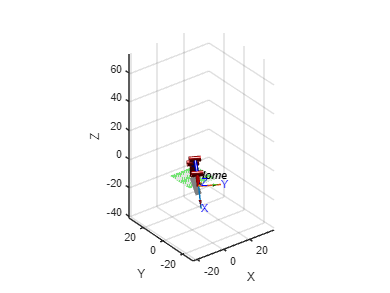

 l = [0, 10.2, 10.2, 7.8];
 a=152.05-90;
 b=136.82-90;
 c= 74.12;
 d=108.40-90;
 q = [a, b, c, d]*pi/180;
 offset = [0, pi/2, 0, 0];
 DHparameters = [q(1) 5.4 l(1) pi/2 0 offset(1);
                 q(2) 0   l(2) 0    0 offset(2);
                 q(3) 0   l(3) 0    0 offset(3);
                 q(3) 0   l(4) pi/2 0 offset(4)                ];
 L21(1) = Link(DHparameters(1,:));
 L21(2) = Link(DHparameters(2,:));
 L21(3) = Link(DHparameters(3,:));
 L21(4) = Link(DHparameters(4,:));
 Robot_punto21 = SerialLink(L21,'name','Home');
 ws2_2 = [-10 10 -10 10 -4.5 40];
 Robot_punto21.plot(q,'workspace',ws2_2);
 xlim([-22.0 39.5])
 ylim([-29.8 34.7])
 zlim([-41.0 73.7])